# Simulation results elaboration

## Constant Volatility

Load results and initialize indicators.

load("simulation_constantVolatility.mat");

numSigma = length(sigma_values);
numPoolRecoveryPeriod = length(poolRecoveryPeriod_values);
numBaseVirtualPool = length(baseVirtualPool_values);

Compute values

function MSE = computeMSE(realValues, expectedValues)
if length(realValues) ~= length(expectedValues)
    error('Vector lengths must be the same.');
end
err = realValues - expectedValues;
temp = mean(err .^ 2);
MSE = temp(1);
end

% when the stablecoin price falls below $0.95 or above $1.05
numberOfDepegEvents = zeros(numSigma, numPoolRecoveryPeriod, numBaseVirtualPool);
% when the stablecoin falls below 0.8 and collateral prices fall below $0.2
numberOfCollapes = zeros(numSigma, numPoolRecoveryPeriod, numBaseVirtualPool);
% the mean-square-error of the stablecoin price with respect to the
% constant $1 peg
MSEStabilityIndex = zeros(numSigma, numPoolRecoveryPeriod, numBaseVirtualPool);

for sigma = 1:numSigma
    for rp = 1:numPoolRecoveryPeriod
        for base_vlp = 1:numBaseVirtualPool

            mse = 0;

            for i = 1:numSimulations
                % Extract the relevant data for computation
                stablecoinResultArray = results_P_a{sigma, rp, base_vlp, i};
                collateralResultArray = results_P_b{sigma, rp, base_vlp, i};

                % Convert the cell array to a numeric array
                stablecoinPriceHistory = stablecoinResultArray(:);
                collateralPriceHistory = collateralResultArray(:);

                clear stablecoinResultArray;
                clear collateralResultArray;

                if any(stablecoinPriceHistory < 0.95) || any(stablecoinPriceHistory > 1.05)
                    numberOfDepegEvents(sigma, rp, base_vlp) = numberOfDepegEvents(sigma, rp, base_vlp) + 1;
                    if any(stablecoinPriceHistory < 0.5)
                        numberOfCollapes(sigma, rp, base_vlp) = numberOfCollapes(sigma, rp, base_vlp) + 1;
                        fprintf("Collapse! RP: %d; VLP: %d, sigma: %d, iteration: %d\n", sigma, rp, base_vlp, i);
                    end
                end
                mse = mse + computeMSE(stablecoinPriceHistory, ones(length(stablecoinPriceHistory), 1));
            end

            MSEStabilityIndex(sigma, rp, base_vlp) = mse / numSimulations;

        end
    end
end

Display results

fprintf("NUMBER OF DEPEG EVENTS")
for sigma = 1:numPoolRecoveryPeriod
    for rp = 1:numBaseVirtualPool
        for base_vlp = 1:numSigma
            fprintf("(sigma=%d, RP=%d, BP=%d)    depeg=%d     collapses=%d     MSE=%d\n", ...
                sigma_values(sigma), poolRecoveryPeriod_values(rp), baseVirtualPool_values(base_vlp), ...
                numberOfDepegEvents(sigma,rp,base_vlp), numberOfCollapes(sigma,rp,base_vlp), MSEStabilityIndex(sigma,rp,base_vlp));
        end
        fprintf("-----------------\n");
    end
end

sigma = 2;
rp = 1;
base_vlp = 1;
i = 1;

plot(results_P_a{sigma, rp, base_vlp, i});
xlim([0 50000]);
xlabel("iterations");
ylabel("stablecoin price");
title("T_s price");

plot(results_probA{sigma, rp, base_vlp, i});
xlim([0 50000]);
xlabel("iterations");
ylabel("prob");
title("T_s sell prob");

plot(results_P_b{sigma, rp, base_vlp, i});
xlim([0 50000]);
xlabel("iterations");
ylabel("collateral price");
title("T_v price");

plot(results_probB{sigma, rp, base_vlp, i});
xlim([0 50000]);
xlabel("iterations");
ylabel("prob");
title("T_v sell prob");

## Increasing Volatility

Load results and initialize indicators.

load("simulation_results_increasingVolatility_original.mat");

numberOfDepegEvents = 0;
numberOfSevereDepegs = 0;
numberOfCollapses = 0;
MSEStabilityIndex = zeros(numel(results), 1);
severeDeppegedSimulations = zeros(numel(results), 1);
collapseTimes = zeros(numel(results), 1);               % when P_a < 0.9

for i = 1:numel(results)

    stablecoinPriceHistory = results{i}.T_aPrices;
    collateralPriceHistory = results{i}.T_bPrices;

    if any(stablecoinPriceHistory < 0.95) || any(stablecoinPriceHistory > 1.05)
        numberOfDepegEvents = numberOfDepegEvents + 1;

        [m, index] = min(stablecoinPriceHistory);
        if m < 0.9
            numberOfSevereDepegs = numberOfSevereDepegs + 1;
            collapseTimes(i) = find(stablecoinPriceHistory<0.9, 1);
            capitalizaitonT_a = results{i}.T_aPrices .* results{i}.totalT_aSupply;
            capitalizaitonT_b = results{i}.T_bPrices .* results{i}.totalT_bSupply;
            if capitalizaitonT_a(index) > capitalizaitonT_b(index)
                numberOfCollapses = numberOfCollapses + 1;
            end
        end

    end

    MSEStabilityIndex(i) = computeMSE(stablecoinPriceHistory, ones(length(stablecoinPriceHistory), 1));

end

indexes = find(collapseTimes > 0);
clean_collapseTimes = collapseTimes(collapseTimes > 0);

Display results

disp(["number of depeg events: ", num2str(numberOfDepegEvents)]);

    "number of depeg events: "    "100"



disp(["number of collapses events (p<0.9): ", num2str(numberOfSevereDepegs)]);

    "number of collapses events (p<0.9): "    "71"



disp(["number of recovery form collapse: ", num2str(numberOfSevereDepegs - numberOfCollapses)]);

    "number of recovery form collapse: "    "36"



disp(["mean collapse time: ", num2str(mean(clean_collapseTimes))]);

    "mean collapse time: "    "126771.2817"



disp(["mean MSE: ", num2str(mean(MSEStabilityIndex))])

    "mean MSE: "    "0.070454"



for i = 1:length(MSEStabilityIndex)
    fprintf("MSE(%d) = %d\n", i, MSEStabilityIndex(i));
end

MSE(1) = 1.975170e-02
MSE(2) = 2.304290e-01
MSE(3) = 1.903495e-02
MSE(4) = 1.897315e-03
MSE(5) = 3.945444e-02
MSE(6) = 3.448597e-01
MSE(7) = 7.993423e-02
MSE(8) = 1.911709e-02
MSE(9) = 5.183492e-03
MSE(10) = 2.329082e-01
MSE(11) = 2.720928e-02
MSE(12) = 1.867202e-02
MSE(13) = 2.092401e-02
MSE(14) = 2.275631e-02
MSE(15) = 1.469280e-02
MSE(16) = 2.421307e-02
MSE(17) = 1.885071e-02
MSE(18) = 1.208364e-02
MSE(19) = 3.080570e-02
MSE(20) = 2.671288e-01
MSE(21) = 5.150172e-02
MSE(22) = 2.647655e-01
MSE(23) = 1.905239e-02
MSE(24) = 4.145321e-02
MSE(25) = 1.871469e-02
MSE(26) = 1.883600e-02
MSE(27) = 1.164215e-02
MSE(28) = 1.929113e-02
MSE(29) = 2.185590e-02
MSE(30) = 3.587562e-01
MSE(31) = 1.818789e-01
MSE(32) = 8.615083e-03
MSE(33) = 2.927920e-02
MSE(34) = 5.509014e-03
MSE(35) = 2.352394e-02
MSE(36) = 2.532296e-01
MSE(37) = 2.914282e-03
MSE(38) = 2.204911e-01
MSE(39) = 1.912713e-02
MSE(40) = 1.239761e-02
MSE(41) = 5.614689e-03
MSE(42) = 1.870974e-02
MSE(43) = 1.120080e-01
MSE(44) = 8.677662e-

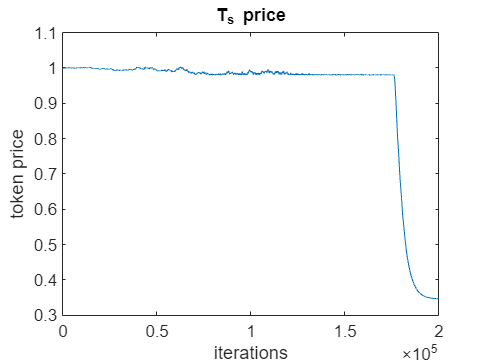

i = 82;

plot(results{i}.T_aPrices);
xlim([0 200000]);
xlabel("iterations");
ylabel("token price");
title("T_s price");

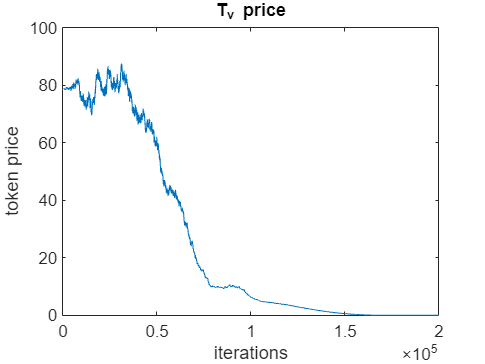


plot(results{i}.T_bPrices);
xlim([0 200000]);
xlabel("iterations");
ylabel("token price");
title("T_v price");

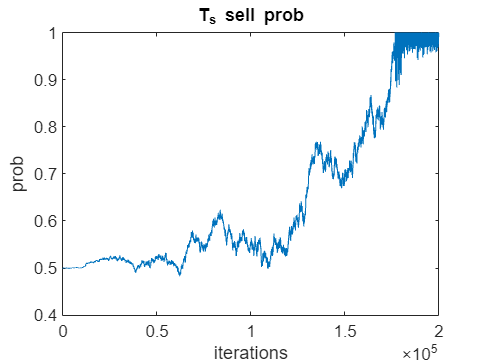


plot(results{i}.probA);
xlim([0 200000]);
xlabel("iterations");
ylabel("prob");
title("T_s sell prob");

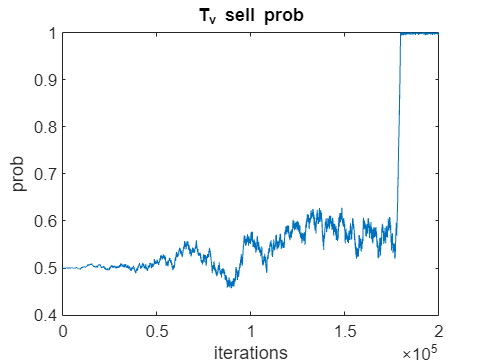


plot(results{i}.probB);
xlim([0 200000]);
xlabel("iterations");
ylabel("prob");
title("T_v sell prob");

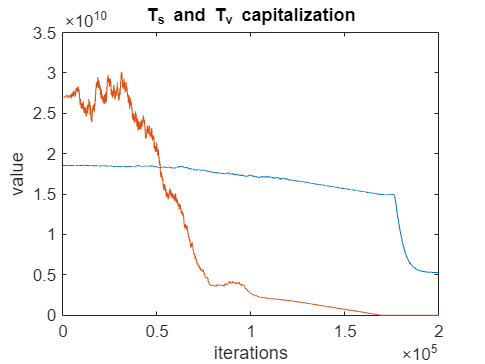


capA = results{i}.T_aPrices .* results{i}.totalT_aSupply;
plot(capA);
xlim([0 200000]);
xlabel("iterations");
ylabel("value");
title("T_s capitalization");
hold on;
capB = results{i}.T_bPrices .* results{i}.totalT_bSupply;
plot(capB);
xlim([0 200000]);
xlabel("iterations");
ylabel("value");
title("T_s and T_v capitalization");
hold off;

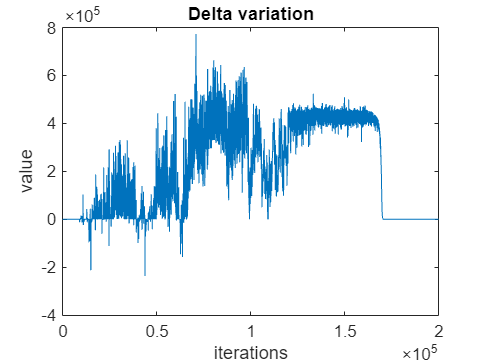


plot(results{i}.delta);
xlim([0 200000]);
xlabel("iterations");
ylabel("value");
title("Delta variation");

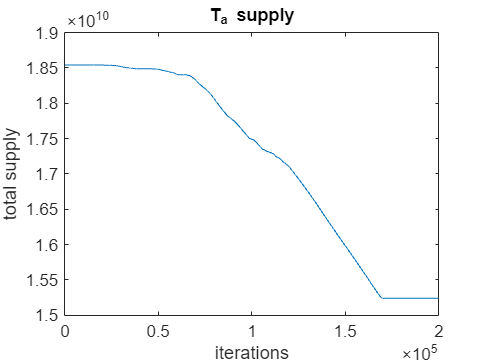


plot(results{i}.totalT_aSupply);
xlim([0 200000]);
xlabel("iterations");
ylabel("total supply");
title("T_a supply");

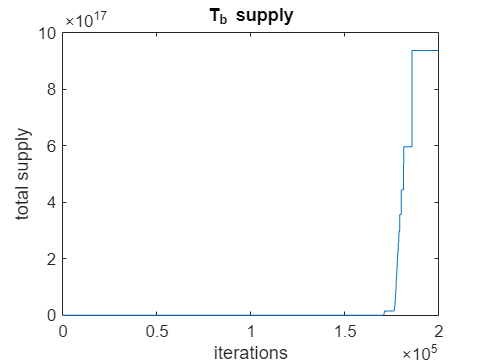


plot(results{i}.totalT_bSupply);
xlim([0 200000]);
xlabel("iterations");
ylabel("total supply");
title("T_b supply");

for idx = 1:length(indexes)   % Usa un ciclo che iteri sui valori di indexes
    i = indexes(idx);
    data = results{i}.T_aPrices;  % Accedi alla cella e ai dati contenuti
    figure
    fprintf("simulation: %d", i);
    plot(data);                   % Plotta i dati
    xlim([0 200000]);
    xlabel("iterations");
    ylabel("token price");
    title("T_s price");
end
